% a)
% labels = calculate_NN(trainv, trainlab, testv, 1000);

labels = labs

labels =      5
     6
     9
     3
     0
     2
     3
     9
     6
     9


incorrect_labels = [;];
correct_labels = [;];
test_size = size(testlab, 1);
for i = 1:test_size
    if testlab(i) ~= labels(i)
        incorrect_labels = [incorrect_labels [i; labels(i)]];
    else
        correct_labels = [correct_labels [i; labels(i)]];
    end
end

size_wrong = size(incorrect_labels)

size_wrong =            2        9094


size_right = size(correct_labels)

size_right =      2   906


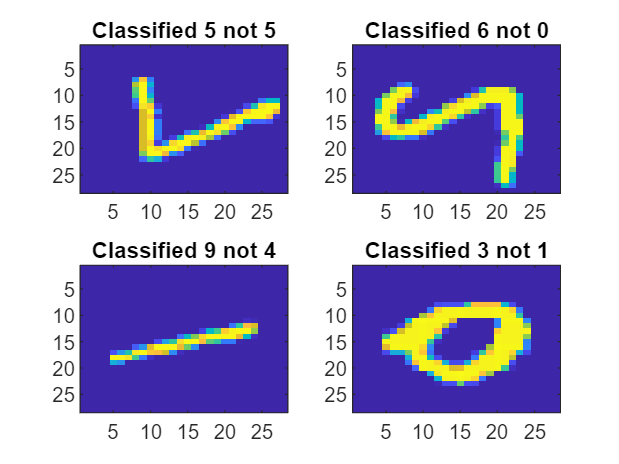


% Plot incorrect labels


error_indeces = randi(size(incorrect_labels), 4);
correct_indeces = randi(size(correct_labels), 4);

for i = 1:4

    
    i_index = incorrect_labels(1, i);
    i_label = incorrect_labels(2, i);


    x = zeros(28, 28);
    x(:) = testv(i_index,:);
    subplot(2, 2, i)
    image(x);
    title(sprintf("Classified %d not %d", i_label, trainlab(i_index)));
end